# first order measured

fmfile3='C:\Users\PhotonUser\My Files\Temporary Files\E3.2.txt';
fmfileID3=fopen(fmfile3);
fmtextstuff3=textscan(fmfileID3, '%s %s %s %s','Delimiter','\t');
fclose(fmfileID3);

fmtime3=string(fmtextstuff3{1,3});
fmtime3=erase(fmtime3,'2/11/2022  14:55:');
fmvolt3=string(fmtextstuff3{1,4});

fmtime3=fmtime3(625:1865);
fmvolt3=fmvolt3(625:1865);

fmtime3=str2double(fmtime3);
fmvolt3=str2double(fmvolt3);

fmtime3=fmtime3-fmtime3(1);
fmvolt3=fmvolt3-fmvolt3(1);

## second order measured

smfile3='C:\Users\PhotonUser\My Files\Temporary Files\E3.3.txt';
smfileID3=fopen(smfile3);
smtextstuff3=textscan(smfileID3,'%s %s %s %s','Delimiter','\t');
fclose(smfileID3);

smtime3=string(smtextstuff3{1,3});
smtime3=erase(smtime3,'2/11/2022  15:18:');
smvolt3=string(smtextstuff3{1,4});

smtime3=smtime3(625:1865);
smvolt3=smvolt3(625:1865);

smtime3=str2double(smtime3);
smvolt3=str2double(smvolt3);

smtime3=smtime3-smtime3(1);
smvolt3=smvolt3-smvolt3(1);

## second order simulated

ssfile3='C:\Users\PhotonUser\My Files\Temporary Files\Lab 3 Exercise 3 sim.csv';
ssdata3=readmatrix(ssfile3);

sstime3=ssdata3(:,1);
ssvolt3=ssdata3(:,2);

## plot

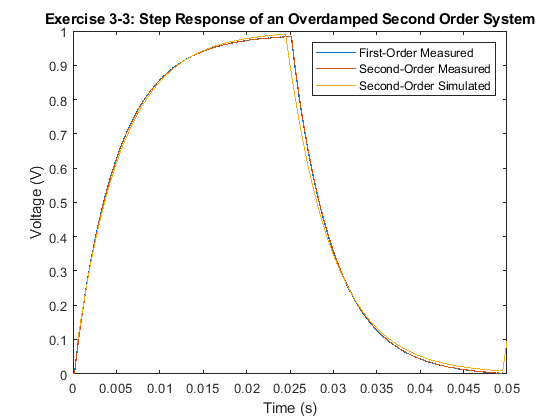

plot(fmtime3,fmvolt3,'DisplayName','First-Order Measured');
hold on
plot(smtime3,smvolt3,'DisplayName','Second-Order Measured');
hold on
plot(sstime3,ssvolt3,'DisplayName','Second-Order Simulated');
hold on 

xlabel('Time (s)');
ylabel('Voltage (V)');
title('Exercise 3-3: Step Response of an Overdamped Second Order System');
legend 
hold off